# **W2 Configuration Space**

#### **Robotics: Computational Motion Planning**

**University of Pennsylvania  |  Coursera**

clear;
close all;
clc;

## Draw Robot And Obstacles

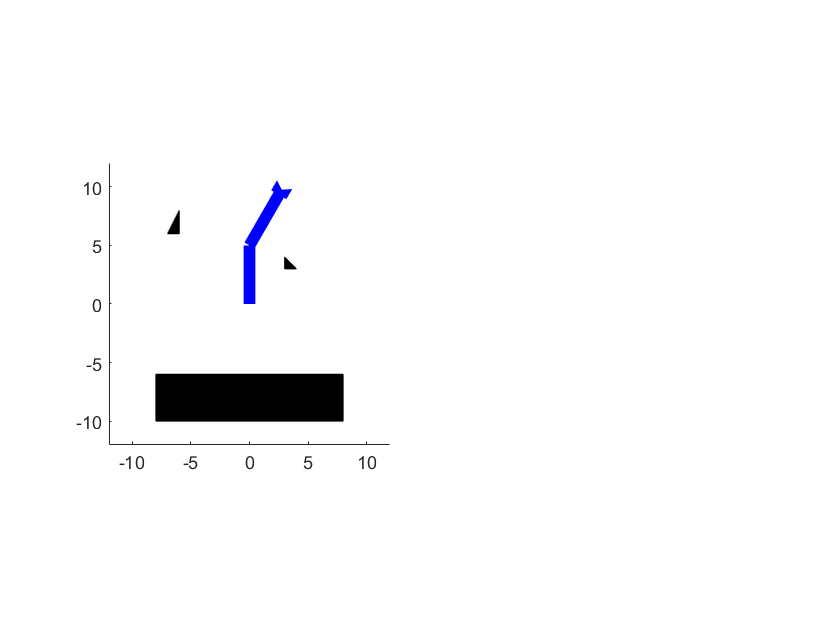

figure(1);

subplot(1,2,1);

% This function sets up the two link robot based on the coordinates
% in configuration space [theta1, theta2]. You can change the configuration
% of the robot by changing the two numbers in the input array.
fv = TwoLinkRobot ([330 90]);

sz = 12;

p = patch (fv);

p.FaceColor = 'blue';
p.EdgeColor = 'none';

hold on;

% These arrays define the vertices and faces of the obstacle as a patch
obstacle.vertices = [3 3; 3 4; 4 3; -6 6; -6 8; -7 6; -8 -6; 8 -6; -8 -10; 8 -10];
obstacle.faces = [1 2 3; 4 5 6; 7 8 9; 8 9 10];

obs = patch(obstacle);

hold off;

axis equal;
axis (sz*[-1 1 -1 1]);

## Compute Configuration Space

theta1_range = 0:2:360;
theta2_range = 0:2:360;

nrows = length(theta2_range);
ncols = length(theta1_range);

cspace = true(nrows, ncols);

for i = 1:nrows
    for j = 1:ncols
        fv = TwoLinkRobot ([theta1_range(j) theta2_range(i)]);
        cspace (i,j) = CollisionCheck (fv, obstacle);
    end
    
    % fprintf ('%d of %d\n', i, nrows);
end

## Plot Configuration Space

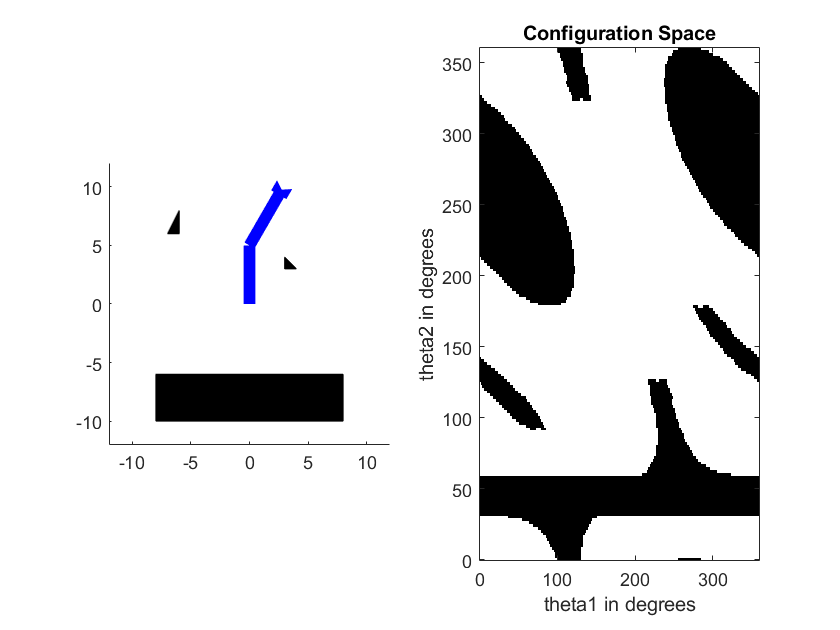

subplot (1,2,2);

axis equal;
axis ([0 360 0 360]);

cmap = [1 1 1; 0 0 0];
colormap(cmap);

% Here we may flip the cspace image to match the axes
imagesc([0 360], [0 360], cspace);
axis xy;

xlabel ('theta1 in degrees');
ylabel ('theta2 in degrees');

title ('Configuration Space');

## Plot A Path Through Torus Space

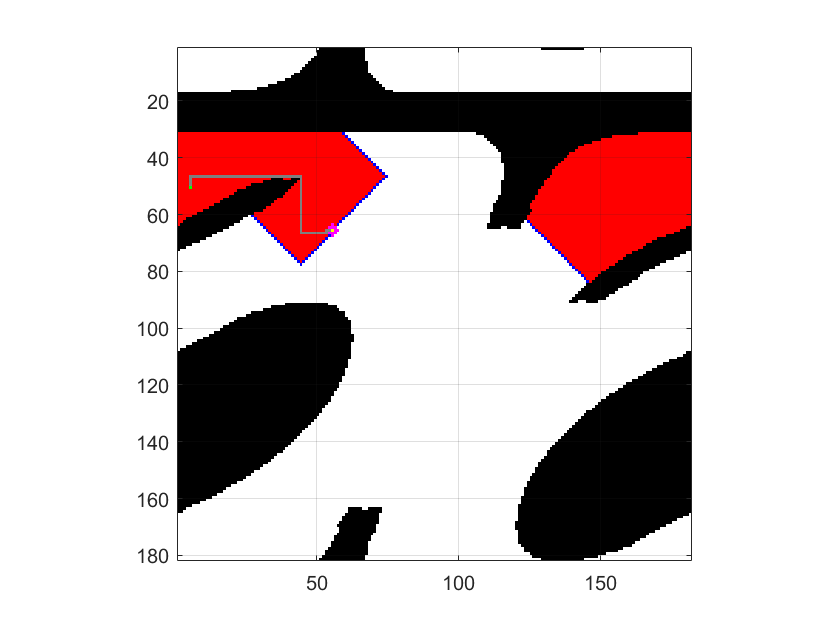

% New figure to visualize progress of planner
figure(2);

% You should experiment by changing these coordinates
start_coords = [50, 5];
end_coords = [65, 55];

% Find a route between the start and end nodes
route = DijkstraTorus (cspace, start_coords, end_coords);

## Animate The Route

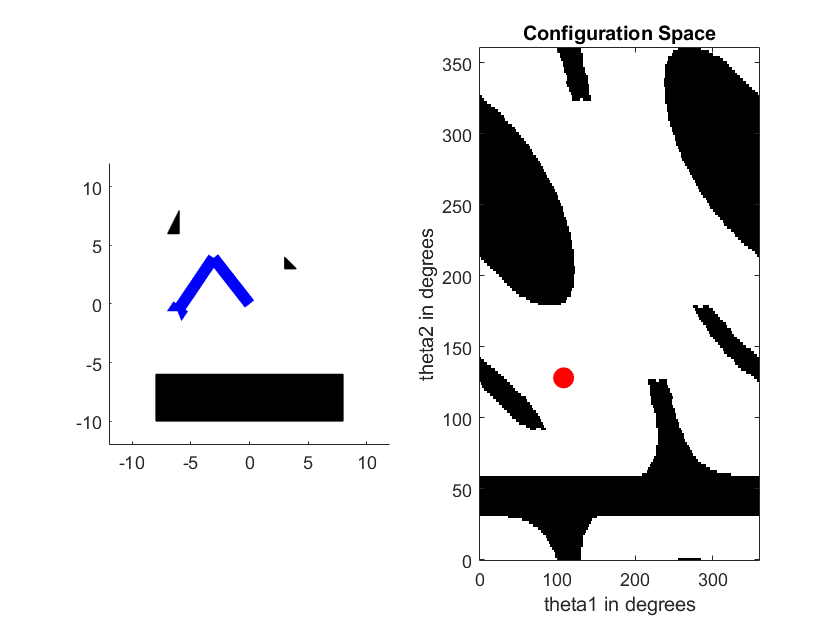

[i,j] = ind2sub (size(cspace), route);

y = theta2_range(i);
x = theta1_range(j);

% Plot point in configuration space
figure(1);
subplot(1,2,2);
hold on;
h = plot (x(1), y(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;

n = length(x);

for i = 1:n
    fv = TwoLinkRobot ([x(i), y(i)]);
    p.Vertices = fv.vertices;
    
    h.XData = x(i);
    h.YData = y(i);
    
    drawnow;
end